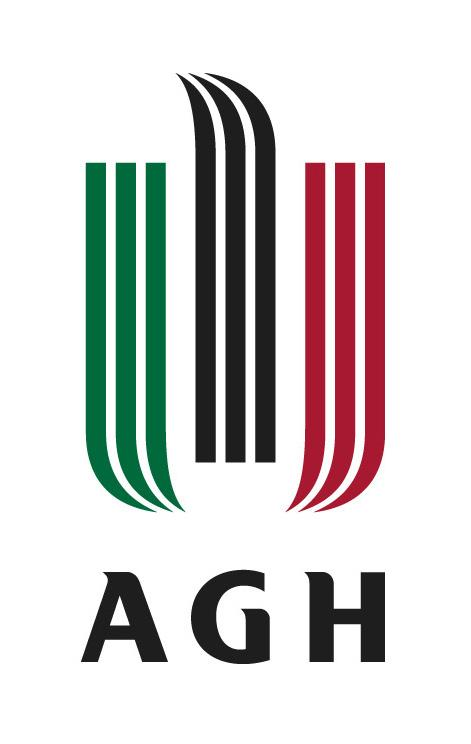

# Dynamics modeling of the two-wheeled mobile robot

#### Mikolaj Suchon

05/06/2025

## Assumptions:

We asume a two wheeled mobile robot along a path consisting of 5 different segments: Startup, straight line movement, arc movement, straignt line movement,deceleration and stop. Values presented below are also depicted in figure 1.

- Acceleration time: 2s

- Max speed: 1m/s

- Straight line movement: 1s

- Arc movement: 2s R=4m

- Straight line movement: 1s

- Decceleration time: 2s

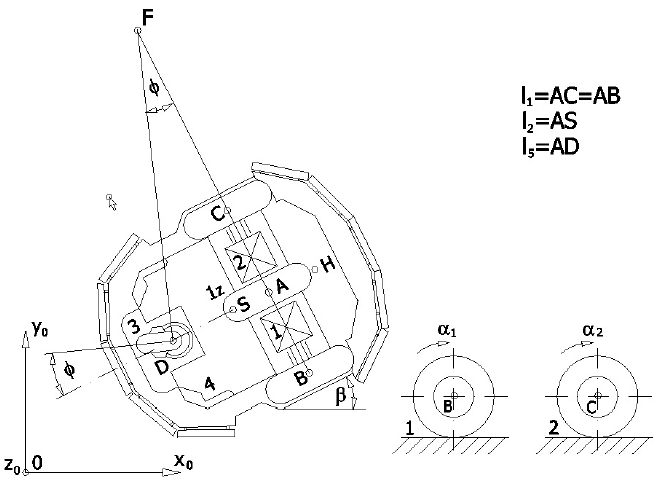

Sketch 1: Robot geometry. Source: prof. Tomasz Buratowski.

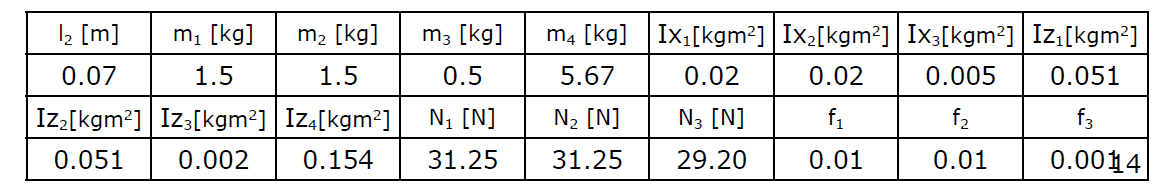

Table 1: Values assumed. Source: prof. Tomasz Buratowski.

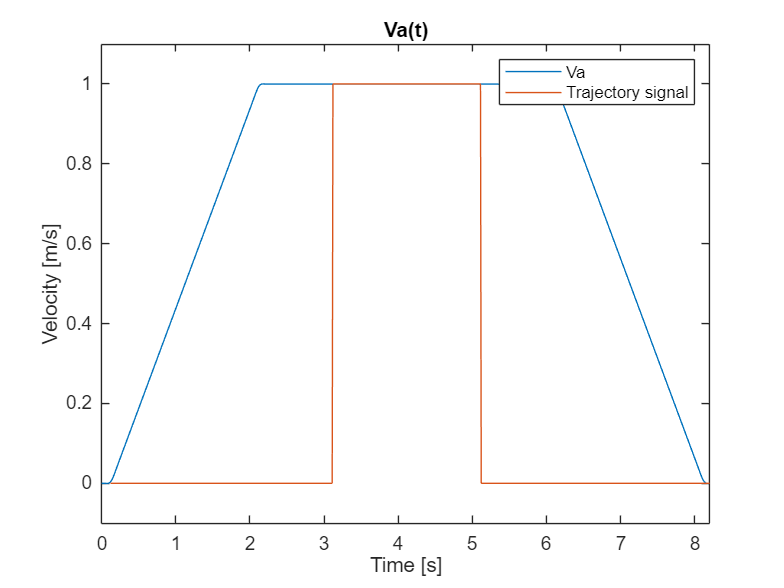

clear
fs=100;
dt=1/fs;
t=0:dt:8-dt;
Va=0.5*t(1:(2*fs));
Va=[Va,ones(1,4*fs)];
Va=[Va,-0.5*t(6*fs+1:8*fs)+4];
trajSig=[zeros(1,3*fs),ones(1,2*fs),zeros(1,3*fs)];
N=length(t);
df=fs/N;
fv = (0:N-1)*df; % frequency vector
[Vas,group_delay] = FilterData([Va,zeros(1,0.3*fs)]);
t2=0:dt:8-dt+0.3;
figure(1)
plot(t2,Vas);hold on
title('Va(t)')
xlabel('Time [s]')
ylabel('Velocity [m/s]')
plot(t2+group_delay*dt,[trajSig,zeros(1,30)]);hold off
legend('Va','Trajectory signal')
xlim([0,8.2])
ylim([-0.1,1.1])

Va=Vas;
Ts=[trajSig,zeros(1,30)];
Va = timeseries(Vas ,t2);
Ts = timeseries([trajSig,zeros(1,30)],t2);

tsim = 8;
R = 3;
r1 = 0.0825 ;
r2 = 0.0825;
r3 = 0.035;
l1 = 0.163;
l3 = 0.07;
l5 = 0.07;

r = r1;
l2 = 0.07;
m1 = 1.5;
m2 = 1.5;
m3 = 0.5;
m4 = 5.67 ;
Ix1 = 0.02;
Ix2 = 0.02;
Ix3 = 0.005;
Iz1 = 0.051;
Iz2 = 0.051;
Iz3 = 0.002;
Iz4 = 0.154;
N1 = 31.25;
N2 = 31.25;
N3 = 29.2;
f1 = 0.015;
f2 = 0.015;
f3 = 0.0015;
h= l1/r1;

out=sim("inverse_dynamics2.slx");

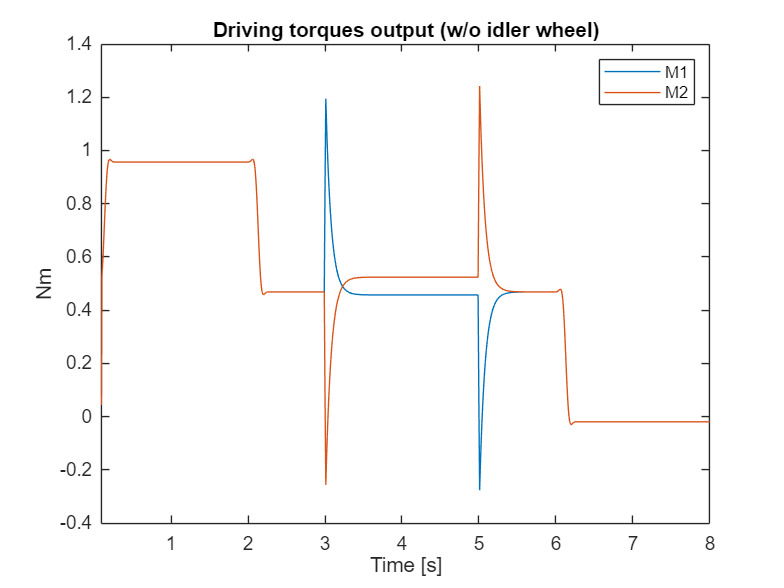

Time=out.M1M2.Time;
M1=out.M1M2.Data(:,1);
M2=out.M1M2.Data(:,2);
figure(2)
plot(Time,M1,Time,M2)
title('Driving torques output (w/o idler wheel)')
xlabel('Time [s]')
ylabel('Nm')
legend('M1','M2')
xlim([0.095 8])

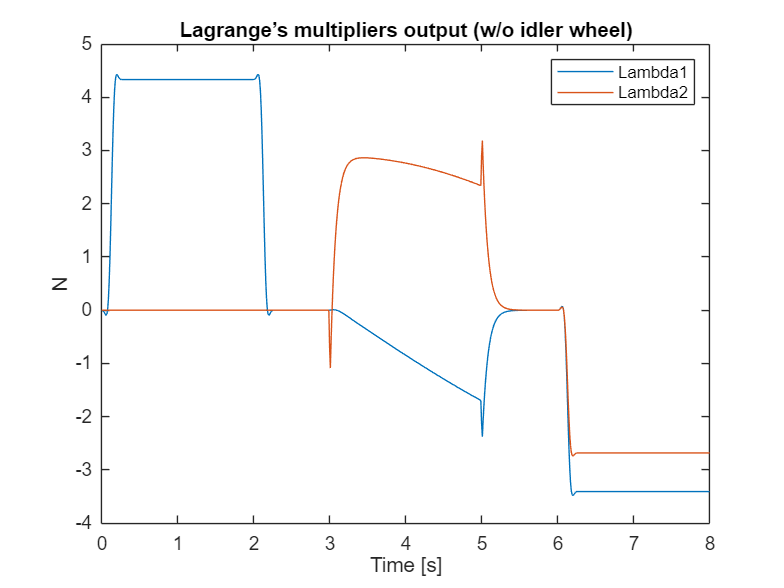


Lambda1=out.Lambda1Lambda2.Data(:,1);
Lambda2=out.Lambda1Lambda2.Data(:,2);
figure(3)
plot(Time,Lambda1,Time,Lambda2)
title('Lagrange’s multipliers output (w/o idler wheel)')
xlabel('Time [s]')
ylabel('N')
legend('Lambda1','Lambda2')

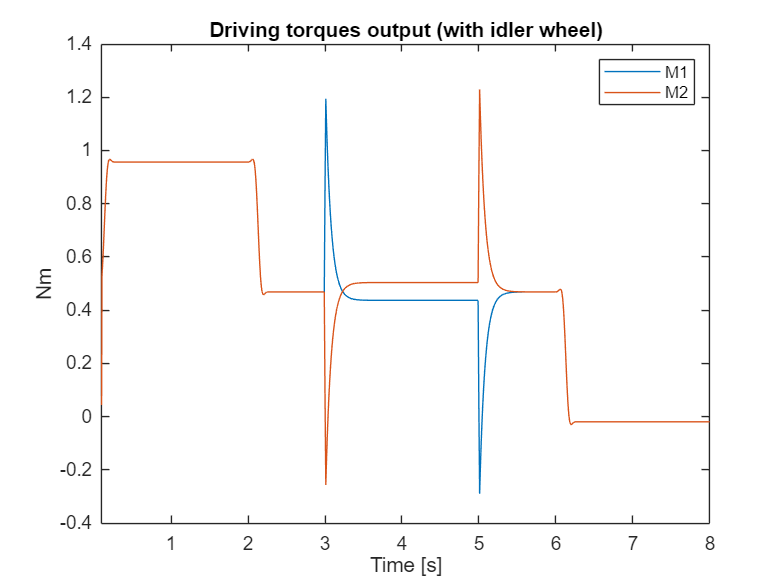

Time=out.M1M2.Time;
M12=out.M1M2withidlerwheel.Data(:,1);
M22=out.M1M2withidlerwheel.Data(:,2);
figure(4)
plot(Time,M12,Time,M22)
title('Driving torques output (with idler wheel)')
xlabel('Time [s]')
ylabel('Nm')
legend('M1','M2')
xlim([0.095 8])

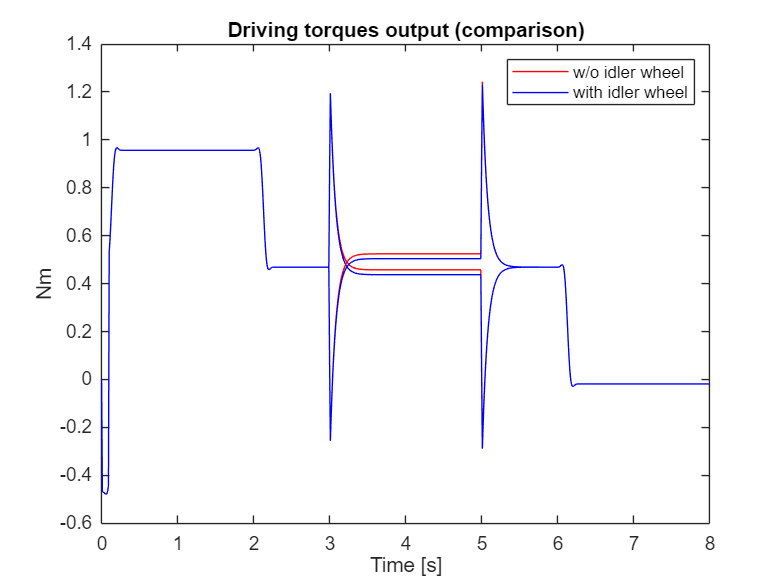

figure(5)
plot(Time,M1,'r',Time,M12,'b');hold on
plot(Time,M2,'r',Time,M22,'b')
xlabel('Time [s]')
ylabel('Nm')
title('Driving torques output (comparison)')
legend('w/o idler wheel','with idler wheel')

function [dataFiltered,group_delay] = FilterData(data)

[n,m]=size(data);

%Forcing row vectros
if n>m
    data=data';
    n=temp;
    n=m;
    m=temp;
end

%Init Filter
Hd=filterF;

%Filtering and scaling all signals one by one
for i=1:n
    
%Applying filter
x=Hd.filter(data(i,:));

%Scaling the filtered signal 
group_delay = floor((length(Hd.Numerator) - 1)/2);
% x = x(group_delay+1:end);

scale_factor = max(data(i,:)) / max(x);
x = x * scale_factor;

%Appending Filtered and scaled signal
dataFiltered(i,:)=x;
end
end


function Hd = filterF
%FILTERF Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.14 and Signal Processing Toolbox 9.2.
% Generated on: 25-Mar-2024 10:36:58

% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 100;  % Sampling Frequency

Fpass = 5;            % Passband Frequency
Fstop = 15;           % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.0001;          % Stopband Attenuation
dens  = 20;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);


% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);

end